# Global thresholding reactions 

This code is designed to execute the global thresholding algorithm.

It is necessary to use COBRAToolbox, a MATLAB toolbox specifically for metabolic network analysis and model reconstruction. The Gurobi solver is also used, although MATLAB's built-in solver can be used.

## Initialize the COBRA Toolbox and set the solver to Gurobi

The Gurobi solver is initialised, as well as COBRAToolbox.

gurobi_setup;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.37.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...     0

     0

Check osense*c - A'*lam - w = 0 (stationarity):
     0
     0


 > [gurobi] Primal optimality condition in solveCobraLP satisfied.
 > [gurobi] Dual optimality condition in solveCobraLP satisfied.


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   --------------------------------------------------------

The objective is linear

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab');
changeCobraSolver('gurobi', 'all');


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only b

## Load data

Gene expression data, the list of housekeeping genes and the metabolic model to be used are uploaded.

CHECK THE DIFFERENCES BETWEEN MODEL AND MODEL_ALICIA

currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
data = readtable("data_TPM.xlsx");
h_k_g = readtable('NM2ENSG.xlsx');
%model = load('Human-GEM_Cobra_v1.01.mat')
%model = model.model
model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
% model_Alicia = load('SysBio_COBRA_v1.17_consensus1.mat');
% model_Alicia = model_Alicia.myModel;

## Ensure the model does not contain blocked reactions

The Genome-Scale Metabolic model may contain blocked reactions, which could affect further analysis, so it is recommended to remove these. 

WE DON'T DO THIS ANYMORE BECAUSE WE ARE LOSING A LOT OF INFORMATION

USE THE PRUNED MODEL TO CALCULATE THE METABOLIC GENES AND REACTIONS, AND THE NOT PRUNE FOR THE HK AND THE CORE GENES AND REACTIONS

% [fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
% model = fluxConsistModel; % load the new model with no blocked reactions
% save('model', 'model');
model_p = load('model.mat');
model_p = model_p.model;
model_genes_p = model_p.genes; % ENSEMBL_IDs of the genes in the model
model_genes = model.genes;
cd(currentFolder)

## Preprocessing

Depending on the dataset, different steps will be required. The points we are interested in obtaining are the ENSEMBL_IDs of the genes, the sample names, and normalising the gene expression data.

To normalise, a log10 of the data is made, to which a 1 is added to avoid that values that are 0 give -inf values.

Finally, a table is created with the new normalised data, the column names are the sample names, and the first column is the ENSEML_IDs.

% Colect the data needed to create the table
Ensembl_id = data(:, 1);
sampleNames = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
%logged_data = log10(data_to_log + 1); % Normalize the data (+1 to avoid having 0 values) 

%Create the new table with the data obtained before
log_data = [Ensembl_id, array2table(data_to_log)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = sampleNames; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)

## Processing the gene expression dataset

Not all genes in the dataset are metabolism-related genes. This part of the code is responsible for obtaining the expression of the metabolic genes (metabolic_genes).

% UNPRUNED MODEL
geneExpressionMatrix = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1}; %- min(log_data{:, i + 1}); % shift minimum to 0 ¡¡ ASK MARIAN HOW HE WANT TO NORMALIZE IT!! ACTUALLY IT SAYS FPKM, SO I ALREADY HAVE IT
    [geneList, geneExpression] = findUsedGenesLevels(model, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix = [geneExpressionMatrix, geneExpression'];
    log_data.value = [];
end

metabolic_genes = array2table(geneExpressionMatrix, 'RowNames', geneList, 'VariableNames', sampleNames);

% Delete the NaN values
metabolic_genes = rmmissing(metabolic_genes, 'MinNumMissing', size(metabolic_genes, 2)); % So we can use the local thresholding 

% Take the metabolic ENSEMBL_IDs for later
gene_names = metabolic_genes.Properties.RowNames;

% PRUNED MODEL
geneExpressionMatrix_P = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1}; %- min(log_data{:, i + 1}); % shift minimum to 0 ¡¡ ASK MARIAN HOW HE WANT TO NORMALIZE IT!! ACTUALLY IT SAYS FPKM, SO I ALREADY HAVE IT
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', sampleNames);

% Delete the NaN values
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); % So we can use the local thresholding 

% Take the metabolic ENSEMBL_IDs for later
gene_names_P = metabolic_genes_P.Properties.RowNames;

## Global thresholding to determine core and non-core genes

DO A PLOT, FOR 25% OF THE GENES HOW MANY CORE REACTIONS OUT OF ALL THE REACTIONS

This part of the code goes through the samples, setting a threshold based on the 75th percentile. All genes with an expression above that threshold are considered core-gene. These core-genes (their ENSEMBL_ID) is stored inside the resutls_CoreGenes structure.

results_CoreGenes = table;
numSamples = length(sampleNames);
Percentile75 = zeros(1, numSamples);
Gene_exp_norm = zeros(length(gene_names_P), numSamples);

for i = 1:numSamples
    col_name = sampleNames{i};
    expData = metabolic_genes(:, col_name);
    expData.Properties.VariableNames{1} = 'ExpressionValue';
    Percentile75_value = prctile(expData.ExpressionValue, 75);

    expData_P = metabolic_genes_P(:, col_name);
    expData_P.Properties.VariableNames{1} = 'ExpressionValue';
    %expData.LogExpressionValue = log10(expData.ExpressionValue + 1);
    expData_P.Value = expData_P.ExpressionValue; %- min(expData.LogExpressionValue);
    %Percentile75_value = prctile(expData.Value, 75);
    expData_P.Value = expData_P.Value/Percentile75_value;
    Gene_exp_norm(:, i) = expData_P.Value;
    coreGenesIdx = expData_P.Value >= 1; % Percentile 75
    coreGenes = expData_P(coreGenesIdx, :);
    coreGeneIDs = coreGenes.Properties.RowNames;
    results_CoreGenes{i, 'Sample'} = {col_name};
    results_CoreGenes{i, 'CoreGeneIDs'} = {coreGeneIDs};
    Percentile75(i) = Percentile75_value;
end


disp(results_CoreGenes);

         Sample         CoreGeneIDs 
    ________________    ____________

    {'BJ_Y1'       }    {585×1 cell}
    {'BJ_Y2'       }    {585×1 cell}
    {'BJ_Y3'       }    {585×1 cell}
    {'BJ_OLD_1'    }    {591×1 cell}
    {'BJ_OLD_2'    }    {593×1 cell}
    {'BJ_OLD_3'    }    {592×1 cell}
    {'IMR90_Y1'    }    {583×1 cell}
    {'IMR90_Y2'    }    {587×1 cell}
    {'IMR90_Y3'    }    {583×1 cell}
    {'IMR90_O1'    }    {581×1 cell}
    {'IMR90_O2'    }    {592×1 cell}
    {'IMR90_O3'    }    {594×1 cell}
    {'WI_38_Y1'    }    {582×1 cell}
    {'WI_38_Y2'    }    {583×1 cell}
    {'WI_38_Y3'    }    {582×1 cell}
    {'WI_38_O1'    }    {588×1 cell}
    {'WI_38_O2'    }    {588×1 cell}
    {'WI_38_O3'    }    {594×1 cell}
    {'HFF_PD16_1'  }    {582×1 cell}
    {'HFF_PD16_2'  }    {581×1 cell}
    {'HFF_PD16_3'  }    {583×1 cell}
    {'HFF_PD74_1'  }    {588×1 cell}
    {'HFF_PD74_2'  }    {583×1 cell}
    {'

## Map genes to reactions for each sample and determine the core reactions

We also want to measure the accuracy of the core-reactions. This part of the code, based on the genes, obtains its expression and based on it the reactions are obtained using the mapExpressionToReactions function. Using the value of the percentile 75 we stabilsh the core-reactions in CoreReact_Sample.

% %Initialize variables
Rxns_global = [];
geneUsed_global = {};
parsedGPR_global = {};
CoreReactions = [];

results_CoreReact = table;
numSamples = length(sampleNames);
expData_P.gene = gene_names_P;

for i = 1:numSamples
    col_name = sampleNames{i};
    expData_P = array2table(Gene_exp_norm(:, i))%expData_P = Gene_exp_norm%(metabolic_genes_P(:, col_name)./Percentile75(:, i));
    expData_P.gene = gene_names_P;
    expData_P.Properties.VariableNames{1} = 'ExpressionValue';
    %expData.LogExpressionValue = log10(expData.ExpressionValue + 1);
    expData_P.value = expData_P.ExpressionValue;%LogExpressionValue; %- min(expData.LogExpressionValue);

    expressionDataSample = struct();
    expressionDataSample.gene = expData_P.Properties.RowNames;
    expressionDataSample.value = expData_P(:, 1: end); % Selecting the column for the current sample

    expressionDataSample.value = table2array(expData_P(:, 'value')); 

    % Map expression data to reactions for the current sample
    [expressionRxns, parsedGPR, gene_used] = mapExpressionToReactions(model_p, expressionDataSample, 'false');
    Rxns_global = [Rxns_global, expressionRxns]; % Store the mapped reactions
    geneUsed_global{i} = gene_used; % Store the genes used in the mapping
    parsedGPR_global{i} = parsedGPR; % Store the genes used in the mapping GO THROUGH IT!!!!!

    %activeReactions = find(Rxns_global >= 1);
    CoreReact_Sample{i} = model_p.rxns(Rxns_global >= 1);  % Keep active reactions names for each sample
    %oreReactions{i} = model_p.rxns(Rxns_global >= Percentile75(:, i));
end

expData_P = 2393×1 table
       Var1   
    __________

        2.0586
        3.0952
       0.12843
      0.049971
        1.1461
    0.00038468
             0
      0.071407
      0.030905
     0.0039738
        1.5709
     0.0020458
         2.216
       0.01037
    0.00082861
       0.37469


expData_P = 2393×1 table
       Var1   
    __________

        1.8369
        2.9635
       0.13584
      0.042985
        1.1926
    0.00055865
     0.0017895
       0.05458
      0.038871
     0.0023084
         1.526
    0.00074275
        2.2753
      0.013553
    0.00060168
       0.36665


expData_P = 2393×1 table
       Var1   
    __________

        2.0952
        2.9615
       0.14845
      0.058897
        1.1913
    0.00074924
    0.00053333
      0.047987
      0.037621
     0.0023219
        1.5316
             0
        2.1418
      0.015709
    0.00053797
       0.36407


expData_P = 2393×1 table
       Var1   
    __________

        1.9656
         3.521
       0.17956
      0.060465
        1.2706
     0.0008289
    0.00088504
       0.54798
      0.030324
     0.0017125
         1.362
     0.0011021
        2.4413
      0.012662
    0.00089275
       0.34081


expData_P = 2393×1 table
       Var1   
    __________

        2.0049
         3.454
       0.18824
      0.073583
        1.3063
    0.00025568
             0
       0.51542
      0.028978
     0.0013206
         1.287
    0.00067988
        2.2417
      0.011028
    0.00055076
       0.37834


expData_P = 2393×1 table
       Var1   
    __________

        1.9944
         3.501
       0.19791
      0.061797
        1.3379
     0.0010307
             0
       0.48839
      0.033024
     0.0035491
        1.3384
    0.00091357
        2.3454
      0.017905
             0
       0.38224


expData_P = 2393×1 table
       Var1   
    __________

        2.8917
         3.939
       0.46917
      0.049646
        1.2973
    0.00036531
     0.0023403
     0.0023794
      0.023584
         1.077
        1.5228
             0
        3.1928
     0.0072215
             0
       0.45302


expData_P = 2393×1 table
      Var1   
    _________

       2.6804
       3.8948
      0.50313
     0.055441
       1.2702
     0.002424
     0.004026
    0.0048241
     0.025888
       1.1688
       1.4714
            0
       3.0589
    0.0062922
            0
      0.46723


expData_P = 2393×1 table
      Var1   
    _________

       3.1082
       3.8969
      0.52083
      0.04549
       1.2748
    0.0023226
    0.0039679
    0.0030256
     0.028656
       1.1171
       1.5112
            0
       3.3457
     0.012522
            0
      0.45961


expData_P = 2393×1 table
      Var1   
    _________

       3.0776
       3.9475
      0.53355
     0.063238
        1.364
    0.0018797
     0.001338
    0.0061216
     0.029215
       1.1482
       1.5693
            0
        3.207
    0.0067561
            0
      0.44567


expData_P = 2393×1 table
      Var1   
    _________

       2.8136
       2.4459
      0.73771
      0.12677
       1.3513
    0.0021004
            0
     0.015732
     0.018683
        2.204
       1.2869
            0
       2.8821
     0.066433
            0
      0.32789


expData_P = 2393×1 table
       Var1   
    __________

        2.3659
        2.1285
       0.64078
       0.12371
        1.5107
      0.002172
     0.0028989
      0.026967
      0.021033
       0.41593
       0.96087
    0.00072194
        3.2616
       0.15467
    0.00058482
       0.31459


expData_P = 2393×1 table
       Var1   
    __________

        2.7974
        3.6653
       0.44931
      0.060566
        1.5709
    0.00079058
             0
      0.004291
      0.028733
       0.59972
        1.3992
             0
         3.951
     0.0071037
             0
       0.48961


expData_P = 2393×1 table
       Var1   
    __________

         2.743
        3.7661
       0.47485
      0.039098
        1.4867
     0.0020238
    0.00072029
     0.0076893
      0.027583
         0.592
        1.4012
             0
        3.9945
      0.011517
             0
       0.50134


expData_P = 2393×1 table
       Var1   
    __________

        2.8385
        3.8039
       0.48741
      0.035969
        1.4522
    0.00039995
             0
     0.0032563
      0.039018
       0.58421
        1.4028
     0.0010635
        3.9384
        0.0115
             0
       0.48278


expData_P = 2393×1 table
       Var1   
    __________

        3.2885
        3.6391
       0.56993
      0.051486
        1.7792
      0.018002
    0.00066281
      0.052056
      0.025382
       0.31967
        1.1221
      0.002476
        3.3851
       0.17515
    0.00066858
       0.31938


expData_P = 2393×1 table
      Var1   
    _________

       3.7084
       3.6093
      0.59362
      0.04881
       1.7468
     0.015767
            0
     0.048829
      0.03149
      0.34012
       1.1479
    0.0016441
       3.1625
       0.1939
            0
      0.32763


expData_P = 2393×1 table
      Var1   
    _________

       3.8021
       3.8317
      0.61788
     0.043549
       1.8418
     0.014761
            0
     0.049216
     0.034791
      0.28791
       1.1429
    0.0028037
       3.3551
      0.19769
            0
      0.28824


expData_P = 2393×1 table
       Var1   
    __________

        2.5298
        2.9385
        0.1525
      0.088678
        1.3214
    0.00074784
     0.0010646
      0.013801
      0.037908
     0.0018026
         1.787
             0
        2.1259
     0.0094075
             0
        0.3579


expData_P = 2393×1 table
       Var1   
    __________

        2.6567
        3.0227
       0.13887
       0.10032
         1.292
             0
             0
      0.014485
      0.041021
     0.0019691
        1.7822
    0.00084479
        2.1037
     0.0079931
    0.00068434
       0.35206


expData_P = 2393×1 table
       Var1   
    __________

        2.6129
        3.0971
       0.13375
      0.085242
        1.3846
    0.00099966
             0
      0.022789
      0.038244
     0.0013769
        1.8353
             0
        2.2406
     0.0041918
     0.0014355
       0.31211


expData_P = 2393×1 table
       Var1   
    __________

        2.6505
        3.7426
       0.22925
      0.063311
        1.1277
     0.0017599
     0.0052616
         1.191
      0.040398
    0.00072722
        1.1183
    0.00093596
        2.3861
      0.045544
             0
       0.27938


expData_P = 2393×1 table
      Var1   
    _________

       2.2133
       3.7399
      0.21406
     0.071147
       1.1658
    0.0018737
    0.0048013
       1.2844
     0.033869
    0.0003871
       1.1265
    0.0049822
       2.1817
     0.030304
            0
      0.26201


expData_P = 2393×1 table
      Var1   
    _________

        2.182
       3.7002
      0.22407
     0.086169
       1.2269
     0.001358
    0.0057999
       1.2687
     0.023866
            0
       1.0981
            0
       2.1506
     0.031726
    0.0029252
       0.2747


expData_P = 2393×1 table
       Var1   
    __________

         2.201
        4.3435
       0.53756
       0.10637
        1.1578
     0.0034643
     0.0033626
     0.0030769
      0.037501
        1.1065
        1.1947
     0.0025123
        2.6815
     0.0033958
    0.00067838
       0.42585


expData_P = 2393×1 table
       Var1   
    __________

        2.2359
        4.4097
       0.50869
       0.11976
        1.3032
     0.0045395
     0.0025851
     0.0049278
      0.036471
         1.183
        1.2228
    0.00080473
         2.705
     0.0016316
             0
       0.40324


expData_P = 2393×1 table
       Var1   
    __________

        2.3411
        4.4824
       0.51193
      0.085009
        1.1986
     0.0040236
     0.0030687
     0.0046798
      0.032986
        1.0528
         1.267
    0.00076423
         2.999
      0.002066
             0
       0.37978


expData_P = 2393×1 table
      Var1   
    _________

       2.0165
       3.6338
      0.48331
     0.094244
       1.9083
    0.0060457
            0
    0.0093521
     0.017781
       0.4303
       0.9873
    0.0024114
       2.8238
      0.29335
            0
      0.36688


expData_P = 2393×1 table
      Var1   
    _________

       2.1525
       3.8898
      0.62197
     0.076673
       1.8766
    0.0072761
    0.0021188
    0.0096936
     0.019928
      0.43355
       1.0455
            0
       2.8318
      0.27578
            0
      0.35268


expData_P = 2393×1 table
       Var1   
    __________

        2.3145
        3.9505
       0.64315
       0.08663
        1.8618
     0.0073356
    0.00071204
     0.0081441
       0.02344
       0.39543
        1.0546
    0.00088664
        2.8345
       0.25227
             0
       0.35044


expData_P = 2393×1 table
       Var1   
    __________

        2.3632
        2.6726
       0.16657
       0.10388
        1.3317
    0.00080793
     0.0005751
       0.10963
      0.045591
     0.0011128
         1.534
    0.00071611
        1.8624
     0.0077436
             0
       0.29311


expData_P = 2393×1 table
       Var1   
    __________

         2.339
        2.7451
       0.18397
      0.088932
        1.4017
     0.0010269
             0
       0.13098
      0.042233
     0.0010608
        1.4613
     0.0018204
        1.9064
      0.011688
    0.00073733
       0.25137


expData_P = 2393×1 table
      Var1   
    _________

       2.3279
       2.6734
      0.17814
     0.098527
       1.3768
      0.00136
    0.0014521
      0.10851
     0.037559
            0
       1.5795
            0
       1.9284
     0.005499
            0
      0.30949


expData_P = 2393×1 table
       Var1   
    __________

        2.4057
        2.5129
       0.23429
       0.12182
        1.2114
      0.001016
     0.0014464
      0.095397
      0.033037
    0.00034983
        1.2667
             0
        2.1267
      0.013998
             0
       0.31199


expData_P = 2393×1 table
       Var1   
    __________

        2.5446
        2.6314
       0.23302
       0.13519
         1.207
    0.00033824
             0
       0.08757
      0.032026
     0.0003494
        1.2325
             0
        2.1426
      0.015804
             0
       0.30417


expData_P = 2393×1 table
       Var1   
    __________

        4.8563
         3.502
       0.20755
      0.014806
        1.2826
     0.0010583
      0.000565
      0.074962
      0.039476
             0
        1.4063
    0.00070353
        5.2468
      0.020445
    0.00056992
       0.25538


expData_P = 2393×1 table
      Var1   
    _________

       2.3034
       2.8285
       0.2755
      0.11581
       1.2404
    0.0009007
    0.0019234
       0.1056
     0.037904
    0.0012406
       1.1312
     0.002395
       1.9409
     0.020503
            0
       0.2997


expData_P = 2393×1 table
       Var1   
    __________

        2.5894
        2.9463
       0.26808
        0.1146
         1.336
    0.00088905
    0.00094927
      0.085412
      0.043366
     0.0004592
        1.1612
      0.001182
        2.3208
      0.017575
             0
       0.33426


expData_P = 2393×1 table
       Var1   
    __________

        2.5438
        2.7802
        0.2597
      0.097434
        1.3097
     0.0010018
    0.00071308
      0.095697
      0.036888
             0
        1.1861
             0
        2.2613
      0.022203
             0
       0.32745


expData_P = 2393×1 table
       Var1   
    __________

        2.3547
        4.3243
       0.47194
        0.1047
        1.1734
     0.0025765
     0.0022925
     0.0034961
      0.025259
        1.1243
        1.2554
    0.00057093
         2.795
     0.0034727
             0
       0.39938


expData_P = 2393×1 table
      Var1   
    _________

       2.4499
         4.47
       0.5046
     0.094069
       1.1638
    0.0025989
    0.0030832
    0.0028212
     0.025271
       1.0464
        1.317
            0
       2.7725
    0.0010379
            0
      0.43555


expData_P = 2393×1 table
       Var1   
    __________

        2.2723
        4.3504
       0.50486
      0.084249
        1.2352
     0.0019287
     0.0011767
     0.0026918
      0.029646
       0.97568
         1.272
             0
        2.9146
    0.00049514
             0
       0.41315


expData_P = 2393×1 table
       Var1   
    __________

        2.3179
        4.4946
        0.5574
       0.10976
        1.2851
     0.0015398
    0.00054802
      0.003343
      0.022459
        0.8083
        1.3084
             0
        2.6744
             0
             0
       0.43166


expData_P = 2393×1 table
      Var1   
    _________

       2.2593
        4.358
      0.63916
      0.11954
        1.174
    0.0044434
    0.0021897
    0.0016697
     0.024518
       1.0864
       1.2067
            0
       2.5949
            0
            0
      0.44039


expData_P = 2393×1 table
       Var1   
    __________

        2.2647
        4.3263
       0.58964
       0.11358
        1.1975
      0.002607
    0.00055672
     0.0012735
      0.022441
        1.0024
        1.2111
    0.00069322
        2.5137
             0
             0
       0.41557


expData_P = 2393×1 table
      Var1   
    _________

       2.0723
       5.4626
      0.78648
      0.17629
        1.306
    0.0010419
    0.0029665
    0.0067859
     0.022919
       2.2896
       1.1807
            0
        2.423
    0.0031205
            0
      0.40088


expData_P = 2393×1 table
       Var1   
    __________

        2.8687
        6.1774
       0.64281
      0.096041
        1.3993
    0.00094227
     0.0020122
     0.0025572
      0.024333
        1.2041
        1.2818
    0.00083519
        3.7647
     0.0039512
             0
       0.33977


expData_P = 2393×1 table
      Var1   
    _________

       2.5813
       5.4842
      0.80366
      0.17146
       1.4256
     0.002398
    0.0028449
    0.0052062
     0.027904
       2.2374
       1.3051
            0
       2.7857
    0.0014365
            0
      0.41242



% Save the results
save('Rxns_global', "Rxns_global");
save('geneUsed_global', 'geneUsed_global');
save('parsedGPR_global', 'parsedGPR_global');

% Load them
Rxns_global = load('Rxns_global.mat');
Rxns_global = Rxns_global.Rxns_global;
geneUsed_global = load('geneUsed_global.mat');
geneUsed_global = geneUsed_global.geneUsed_global;
parsedGPR_global = load('parsedGPR_global.mat');
parsedGPR_global = parsedGPR_global.parsedGPR_global;


% Define variable
CoreReact_Sample = cell(size(sampleNames));

% % Obtain core reactions names
% for i = 1:length(sampleNames)
%     activeReactions = find(Rxns_global(:, i) >= Percentile75(:, i));
%     CoreReact_Sample{i} = model_p.rxns(activeReactions);  % Keep active reactions names for each sample
% end

## Housekeeping gene analysis

Now it starts the analysis for Housekeeping gene list. As it happens with the dataset, not all the housekeeping genes are related with the metabolism. We choose those ones that are related to the metabolism.

hkg_met = model_p.genes(ismember(model_p.genes, h_k_g.converted_alias));%hkg_met = metabolic_genes(index_names, :);

% To reactions
results_HKReact = findRxnsFromGenes_Alicia(model_p, hkg_met);

Input: string of single gene or cell array of multiple genes



% Extract unique housekeeping reaction names
fields = fieldnames(results_HKReact);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = results_HKReact.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end
housekeep_react_unique = unique(housekeep_react);
disp(housekeep_react_unique);

    {'MAR00001'}
    {'MAR00003'}
    {'MAR00005'}
    {'MAR00006'}
    {'MAR00010'}
    {'MAR00067'}
    {'MAR00080'}
    {'MAR00091'}
    {'MAR00113'}
    {'MAR00114'}
    {'MAR00115'}
    {'MAR00117'}
    {'MAR00118'}
    {'MAR00121'}
    {'MAR00122'}
    {'MAR00129'}
    {'MAR00133'}
    {'MAR00153'}
    {'MAR00154'}
    {'MAR00155'}
    {'MAR00158'}
    {'MAR00164'}
    {'MAR00167'}
    {'MAR00170'}
    {'MAR00173'}
    {'MAR00176'}
    {'MAR00179'}
    {'MAR00183'}
    {'MAR00187'}
    {'MAR00188'}
    {'MAR00190'}
    {'MAR00191'}
    {'MAR00192'}
    {'MAR00195'}
    {'MAR00196'}
    {'MAR00199'}
    {'MAR00200'}
    {'MAR00203'}
    {'MAR00204'}
    {'MAR00208'}
    {'MAR00209'}
    {'MAR00212'}
    {'MAR00213'}
    {'MAR00216'}
    {'MAR00217'}
    {'MAR00225'}
    {'MAR00226'}
    {'MAR00232'}
    {'MAR00233'}
    {'MAR00236'}
    {'MAR00237'}
    {'MAR00240'}
    {'MAR00241'}
    {'MAR00244'}
    {'MAR00245'}
    {'MAR00248'}
    {'MAR00249'}
    {'MAR00254'}
    {'MAR00255

## Compare the number of housekeeping core genes

This part of the code gives the percentage of metabolic core-housekeeping genes out of the total amount of metabolic housekeeping genes 

housekep_core_gene_G = struct("numHousekeepingCoreGenes", [], 'housekeepingCoreGenes', [], 'percentage', []);
totalHousekeepingGenes = numel(hkg_met);

for i = 1:numSamples
    coreGenes = results_CoreGenes.CoreGeneIDs{i};
    housekeepingGeneNames = hkg_met;
    housekeepingInCore_g = ismember(housekeepingGeneNames, coreGenes);
    housekep_core_gene_G(i).numHousekeepingCoreGenes = sum(housekeepingInCore_g);
    housekep_core_gene_G(i).housekeepingCoreGenes = housekeepingGeneNames(housekeepingInCore_g);
    housekep_core_gene_G(i).percentage = (housekep_core_gene_G(i).numHousekeepingCoreGenes / totalHousekeepingGenes) * 100;
end

HK_G_acc_G = [housekep_core_gene_G.percentage];
HK_G_acc_G_col = HK_G_acc_G(:)

HK_G_acc_G_col =    50.8108
   50.8108
   50.8108
   50.9910
   51.1712
   51.1712
   52.4324
   52.2523
   52.0721
   52.0721


T_Genes = table(HK_G_acc_G_col, 'VariableNames', {'HK_G_acc_G'});
writetable(T_Genes, "HK_G_acc_G.xlsx", 'WriteRowNames', false);

## Compare the number of housekeeping core reactions

This part of the code gives the percentage of metabolic core-housekeeping reactions out of the total amount of metabolic housekeeping reactions. 

housekep_core_react_G = struct('numHousekeepingCoreReactions', [], 'housekeepingCoreReactions', [], 'percentage', []);
totalHousekeepingReactions = numel(housekeep_react_unique);

for i = 1:numSamples
    coreReactions = CoreReact_Sample{i};
    housekeepingInCore = ismember(housekeep_react_unique, coreReactions);
    housekep_core_react_G(i).numHousekeepingCoreReactions = sum(housekeepingInCore);
    housekep_core_react_G(i).housekeepingCoreReactions = housekeep_react_unique(housekeepingInCore);
    housekep_core_react_G(i).percentage = (housekep_core_react_G(i).numHousekeepingCoreReactions / totalHousekeepingReactions) * 100;
end

HK_R_acc_G = [housekep_core_react_G.percentage];
HK_R_acc_G_col = HK_R_acc_G(:)

HK_R_acc_G_col =    71.1609
   70.7495
   68.6472
   68.8757
   69.1042
   70.2925
   68.2358
   69.6527
   68.3729
   68.3729


T_React = table(HK_R_acc_G_col, 'VariableNames', {'HK_R_acc_G'});
writetable(T_React, "HK_R_acc_G.xlsx", 'WriteRowNames', false);


# Plot

SOLVE THIS: WITH THE PERCENTAGE METABOLIC GENES THAT ARE IN THE CORE GENE. THRESHOLD FOR UNPRUNED MODEL, AND CORE-GENES AND REACTIONS IN THE PRUNED ONE.

DO THE PLOT WITH THRESHOLDS AND HOUSEKEEPING RECALL FOR GENES. AND FOR REACTIONS

- plot, on the xs the core gene set, and on the y the housekeeping core reactions recall

% Pruned and unpruned data
IMR90_Y2 = table2array(metabolic_genes(:, 8))

IMR90_Y2 = 1.0e+04 *

    0.0123
    0.0178
    0.0023
    0.0003
    0.0058
    0.0000
    0.0000
    0.0001
    0.0000
    0.0001


IMR90_Y2_P = table2array(metabolic_genes_P(:, 8))

IMR90_Y2_P = 1.0e+04 *

    0.0123
    0.0178
    0.0023
    0.0003
    0.0058
    0.0000
    0.0000
    0.0000
    0.0001
    0.0053



% Core genes and core reactions
IMR90_Y2_coreGenes = results_CoreGenes(8, 'CoreGeneIDs');
test = IMR90_Y2_coreGenes{1, 1};
IMR90_Y2_coreGenes = length(test{1, 1})

IMR90_Y2_coreGenes = 587


% for core Reactions
IMR90_Y2_coreReact = CoreReact_Sample(1, 8)

IMR90_Y2_coreReact = 1×1 cell array
    {3038×1 cell}


IMR90_Y2_coreReact = length(IMR90_Y2_coreReact{1, 1})

IMR90_Y2_coreReact = 3038


% Initialises vectors for storing recall values
HK_CG_G = zeros(1, 100);
HK_CR_R = zeros(1, 100);
HK_CG_G_recall_values = zeros(1, 100);
HK_CR_R_recall_values = zeros(1, 100);

% Loop to iterate over each percentile
for p = 1:100
    percentile_value = prctile(IMR90_Y2, p);

    % Normalises data based on the current percentile
    IMR90_Y2_norm = IMR90_Y2_P ./ percentile_value;
    
    % Calculate the recall for core genes
    IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm >= 1);
    HK_CG_G(p) = (length(IMR90_Y2_CG)/IMR90_Y2_coreGenes)*100;
    HK_CG_G_rec = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
    HK_CG_G_recall = (length(HK_CG_G_rec) / length(hkg_met)) * 100;
    HK_CG_G_recall_values(p) = HK_CG_G_recall;
    
    % Prepare the expression data
    expressionData.gene = gene_names_P;
    expressionData.value = IMR90_Y2_norm;
    
    % Map gene expression to reactions
    IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionData, 'false'); % Maybe here with the pruned one?
    IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);
    
    % Calculate the recall for core reactions
    HK_CR_R(p) = (length(IMR90_Y2_CR)/IMR90_Y2_coreReact)*100;
    HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
    HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
    HK_CR_R_recall_values(p) = HK_CR_R_recall;
end


## Graph the results


% total_HKG = 2108;
% HK_CG_G_perc = zeros(1, numel(HK_CG_G)); % Asegúrate de que este tamaño coincida con HK_CG_G
% for i = numel(HK_CG_G):-1:1
%     HK_CG_G_perc(i) = (HK_CG_G(i) / total_HKG) * 100;
% end
% 
% % reactions level
% total_HKR = 6616;
% HK_CR_R_perc = zeros(1, numel(HK_CR_R)); % Asegúrate de que este tamaño coincida con HK_CG_G
% for i = numel(HK_CR_R):-1:1
%     HK_CR_R_perc(i) = (HK_CR_R(i) / total_HKR) * 100;
% end


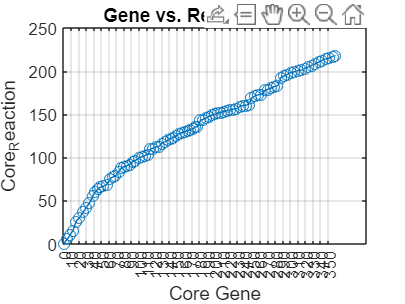

plot(HK_CG_G, HK_CR_R, 'o-');
xlabel('Core Gene');
ylabel('Core_Reaction');
title('Gene vs. Reaction Recall');
grid on;
xticks(0:10:max(HK_CG_G));

% Save the plot
saveas(gcf, 'Gene_vs_Reaction.png');

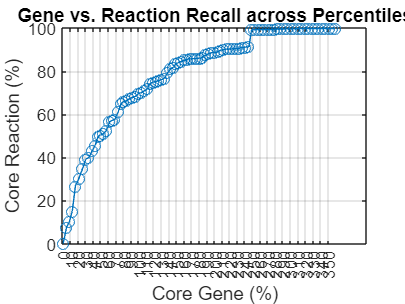

plot(HK_CG_G, HK_CR_R_recall_values, 'o-');
xlabel('Core Gene (%)');
ylabel('Core Reaction (%)');
title('Gene vs. Reaction Recall across Percentiles');
grid on;
xticks(0:10:max(HK_CG_G));

% Save the plot
saveas(gcf, 'Gene_vs_HKReaction.png');

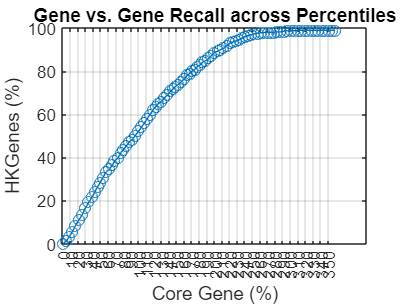

plot(HK_CG_G, HK_CG_G_recall_values, 'o-');
xlabel('Core Gene (%)');
ylabel('HKGenes (%)');
title('Gene vs. Gene Recall across Percentiles');
grid on;
xticks(0:10:max(HK_CG_G));

% Save the plot
saveas(gcf, 'Gene_vs_HKGene.png');

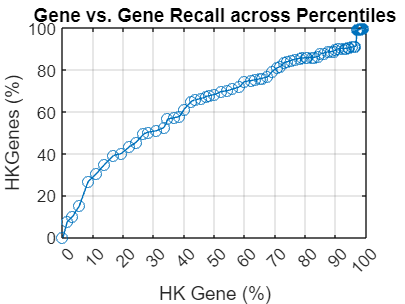

plot(HK_CG_G_recall_values, HK_CR_R_recall_values, 'o-');
xlabel('HK Gene (%)');
ylabel('HKGenes (%)');
title('Gene vs. Gene Recall across Percentiles');
grid on;
xticks(0:10:max(HK_CG_G_perc));

% Save the plot
saveas(gcf, 'HKGene_vs_HKGene.png');

# ADITIONAL CHECK, NOT IMPORTANT

## Check the samples with the same accuracy with genes

Some of the samples have the same accuracy. This part of the code check if the metabolic core-housekeeping genes of those samples are the same or not.

% find the indexes of the same values
 equalIndex = {};

 for i = height(HK_G_acc_G_col)
     index = find(HK_G_acc_G_col == HK_G_acc_G_col(i));
     if length(index) > 1 && ~any(cellfun(@(x) isequal(x, index), equalIndex))
         equalIndex{end+1} = index
     end
 end

% Check the HK core genes names 
genesArray = housekep_core_gene_G.housekeepingCoreGenes;

for i = 1:length(equalIndex)
    indexGrup = equalIndex{i};
    genesGrup = genesArray{indexGrup(1)};
    areEqual = true;
    for j = 2:length(indexGrup)
        genesCompare = genesArray{indexGrup(j)};
        if length(genesGrup) ~= length(genesCompare) || ~all(strcmp(genesGrup, genesCompare))
            areEqual = false;

equalIndex = 1×1 cell array
    {5×1 double}


            break;
        end
    end
    resultsCompare{i} = areEqual;
end

## Check the samples with the same accuracy with reactions

Some of the samples have the same accuracy. This part of the code check if the metabolic core-housekeeping reactions of those samples are the same or not.

% find the indexes of the same values
 equalIndex = {};

 for i = height(HK_R_acc_G_col)
     index = find(HK_R_acc_G_col == HK_R_acc_G_col(i));
     if length(index) > 1 && ~any(cellfun(@(x) isequal(x, index), equalIndex))
         equalIndex{end+1} = index
     end
 end

% Check the HK core genes names 
genesArray = housekep_core_react_G.housekeepingCoreReactions;

for i = 1:length(equalIndex)
    indexGrup = equalIndex{i};
    reactGrup = genesArray{indexGrup(1)};
    areEqual = true;
    for j = 2:length(indexGrup)
        reactCompare = genesArray{indexGrup(j)};

        if length(reactGrup) ~= length(genesCompare) || ~all(strcmp(reactGrup, reactCompare))

equalIndex = 1×1 cell array
    {2×1 double}


            areEqual = false;
            break;
        end
    end
    resultsCompare_R{i} = areEqual;
end
